Resize and pad all photos to 512 x 512

data = batchcropIm('data');

PASSED:/home/echo/bolete/data_pipeline/data/alessioporus-rubriflavus/Alessioporus-rubriflavus-chemicals-on-cap-Igor-Safonov.jpeg
PASSED:/home/echo/bolete/data_pipeline/data/alessioporus-rubriflavus/Alessioporus-rubriflavus-stretched-netting-Jason-Bolin.jpg
PASSED:/home/echo/bolete/data_pipeline/data/aureoboletus-auriflammeus/aureoboletus-auriflammeus-2.jpg
PASSED:/home/echo/bolete/data_pipeline/data/aureoboletus-auriflammeus/aureoboletus-auriflammeus-7.jpg
PASSED:/home/echo/bolete/data_pipeline/data/aureoboletus-auriporus/aureoboletus-auriporus-1.jpg
PASSED:/home/echo/bolete/data_pipeline/data/aureoboletus-auriporus/aureoboletus-auriporus-14.jpg
PASSED:/home/echo/bolete/data_pipeline/data/aureoboletus-auriporus/aureoboletus-auriporus-4.jpg
PASSED:/home/echo/bolete/data_pipeline/data/aureoboletus-auriporus/aureoboletus-auriporus-9.jpg
PASSED:/home/echo/bolete/data_pipeline/data/aureoboletus-flaviporus/Aureoboletus-flaviporus-pores-Darv-DeShazer.jpg
PASSED:/home/echo/bolete/data_pipeline

Gather corresponding labels for each image

names = data.fileName;
newNames = string.empty(length(names),0);
for i=1:length(names)
    sp = split(names{i},'/');
    names(i) = sp(7);
end
data.name = names;
labels = readtable('clean_data/labels.csv');
data = join(data, labels, "LeftKeys","name","RightKeys","NewName");

Cut off species with 5 or fewer pictures

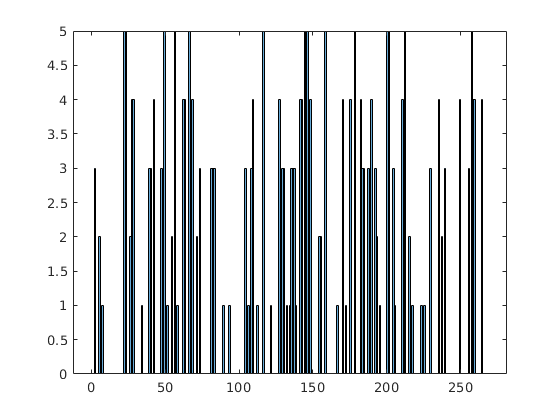

u = unique(data.ID);
[vals, edges] = histcounts(data.ID, [u;length(u)+1]);
keep = ismember(data.ID, u(vals >= 6));
histogram(data.ID(~keep), [u;length(u)+1])

data = data(keep,:);

Move images to matrix

N = height(data);
imageSize = size(data.im{1});
d = zeros(N,imageSize(1), imageSize(2), imageSize(3), "uint8");
ims = data.im;
parfor i = 1:N
    d(i,:,:,:) = ims{i};
end

Compare images and remove similar images

s = compareImages(d, 1e-9);
keep = sum(s) == 1;
d = d(keep,:,:,:);
data = data(keep,:);

Display and count image data

writetable(data(:,"ID"), 'clean_data/image_ids.csv');

Permute the rows of the data so it's randomized

idx = randperm(size(d,1));
assert(size(d,1) == size(data,1));
d = d(idx,:,:,:);
data = data(idx,:);

Remove Existing H5 file

!rm bolete.h5

Create H5 dataset

N = height(data);
imageSize = size(data.im{1});
sz = [Inf, imageSize];
h5create('bolete.h5', '/bolete-images', sz, "Datatype","uint8","ChunkSize", [1 imageSize])

Write images to dataset file

h5write("bolete.h5",'/bolete-images', d, [1, 1, 1, 1], [N, imageSize])

Write labels to dataset file

ids = uint64(data.ID);
h5create('bolete.h5', '/bolete-labels', Inf, "Datatype","uint64","ChunkSize", 1)
h5write("bolete.h5", '/bolete-labels', ids, 1, N)

Write features to file

vars = data.Properties.VariableNames;
characteristics = data{:, vars(find(vars == "F1"):end-5)};
chars = uint8(characteristics);
imageSize = size(chars, 2);
h5create('bolete.h5', '/bolete-characteristics', [Inf imageSize], "Datatype","uint8","ChunkSize", [1, imageSize]);
h5write("bolete.h5", '/bolete-characteristics', chars, [1 1], [N, imageSize]);

Write edibility to file

eds = data{:, vars(end-4:end)};
eds = uint8(eds);
imageSize = size(eds, 2);
h5create('bolete.h5', '/bolete-edibility', [Inf imageSize], "Datatype","uint8","ChunkSize", [1, imageSize]);
h5write("bolete.h5", '/bolete-edibility', eds, [1 1], [N, imageSize]);